## Computer Numbers: Fun with IEEE 754

[IEEE Double Precision Format Youtube Video](https://www.youtube.com/watch?v=8ea09NO7c_U)

MATLAB and most other computing systems use the [IEEE Standard 754](https://en.wikipedia.org/wiki/IEEE_754) to represent a floating-point number in memory. 

A [double presicion floating point](https://en.wikipedia.org/wiki/Double-precision_floating-point_format#:~:text=Double%2Dprecision%20floating%2Dpoint%20format%20(sometimes%20called%20FP64%20or,using%20a%20floating%20radix%20point.) number ***x*** is represented in this standard as *x = (-1)^s * (2^(e-1023)) * (1.f)*, 

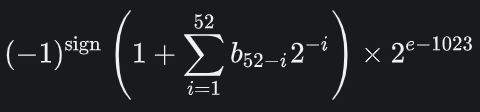

where ***s*** is a 1-bit unsigned integer, ***e*** is an 11-bit unsigned integer, and ***f*** is a 52-bit base-fraction.

The number 1023, called the bias, provides for negative and positive values of the exponent of the 2.

The 64 bits used in this representation of ***x*** can be arranged in memory as shown in the image below.

For example, the real number ***x = 1*** has the binary representation.

*b = **0* *01111111111* *0000000000000000000000000000000000000000000000000000*

*      s          e                                                            f*

using the representation scheme. See the documentation for more information on [floating point numbers in MATLAB](https://www.mathworks.com/help/matlab/matlab_prog/floating-point-numbers.html).

Write a function `binary2Double` using the template below that performs a binary to double conversion. Your function should compute the double precision floating point number ***x***, corresponding to the binary form of the number ***b***, represented by a character string of zeros and ones (read from left to right) using the IEEE Standard 754.

Your function should accept the input:

- b = character string representation of the binary form of a real number, 64 characters

and return the output:

- x = double precision real number corresponding to b

Use the MATLAB function [bin2dec](https://www.mathworks.com/help/matlab/ref/bin2dec.html) to help do this computation. When your solution is complete, test it using the example input provided in the 'Code to call your function' box.

format long;
b = '0011111111110000000000000000000000000000000000000000000000000000';
x = myBinary2Double(b)

x =      1

function x = myBinary2Double(b)
    sign = bin2dec(extract(b,1));
    exp = bin2dec(extractBetween(b,2,12));
    f = extractBetween(b,13,64);
    mant = 1;
    
    for i = 1:1:52
        mant = mant + bin2dec(extractBetween(f,i,i)) * 2^(-i);
    end    
    
    x = (-1)^sign * 2^(exp-1023) * mant;
end